## The Precession of the Perihelion of Mercury

#### Orbital Mechanics Background

The perihelion of a planet's orbit around the sun is the point at which the planet is closest to the sun. The perihelion is one end of the elliptical orbit's semi-major axis, the other end being the aphelion, where the planet is farthest from the sun.

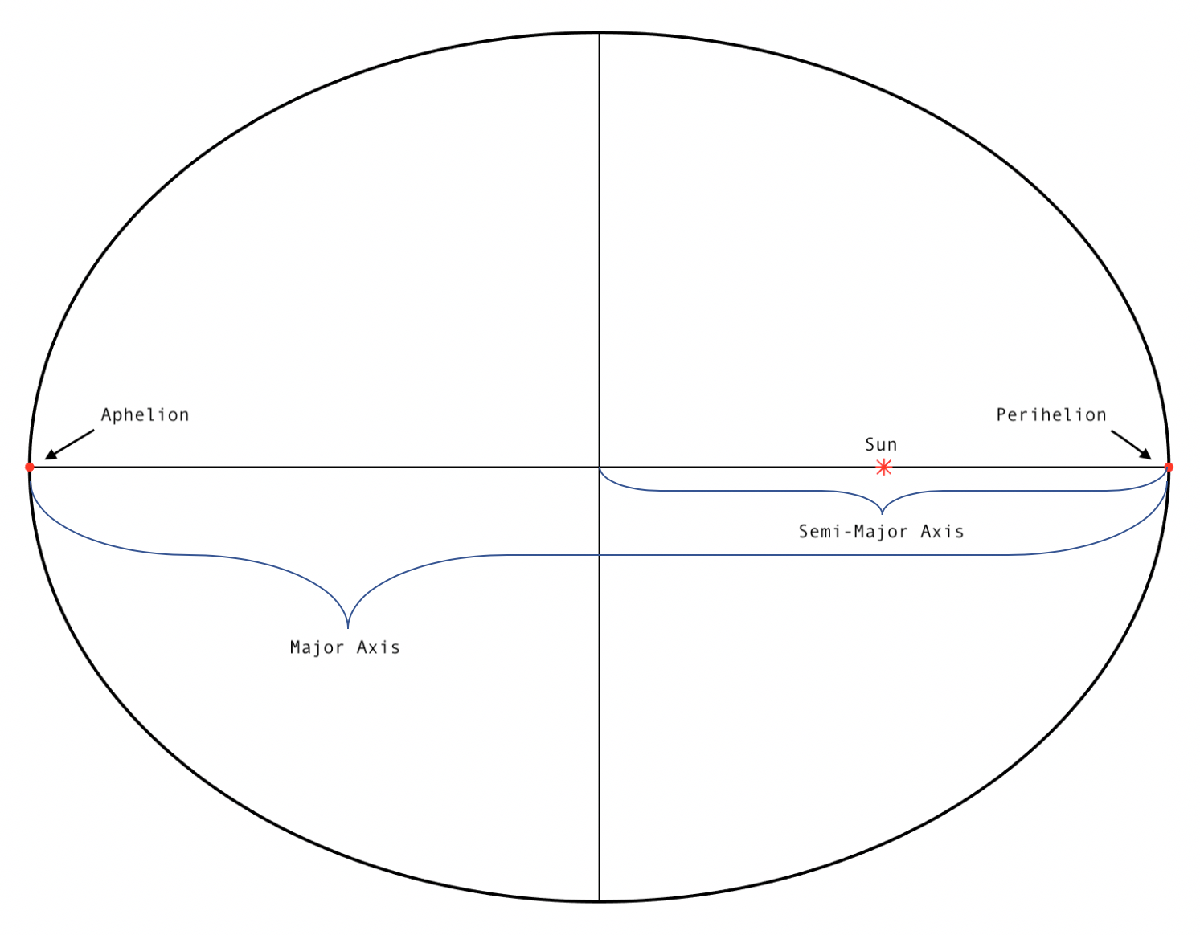

If the perihelion of a planet does not fall at the same position with reference to the fixed stars, the orbit is said to precess. This means the orbit is not a perfect ellipse, but instead follows a rosette trajectory where the starting point of one orbit does not line up with the ending point. This precession of the perihelion can be thought of as the slow rotation of the major axis around the center of mass (in the case the center of mass is essentially the position of the sun).

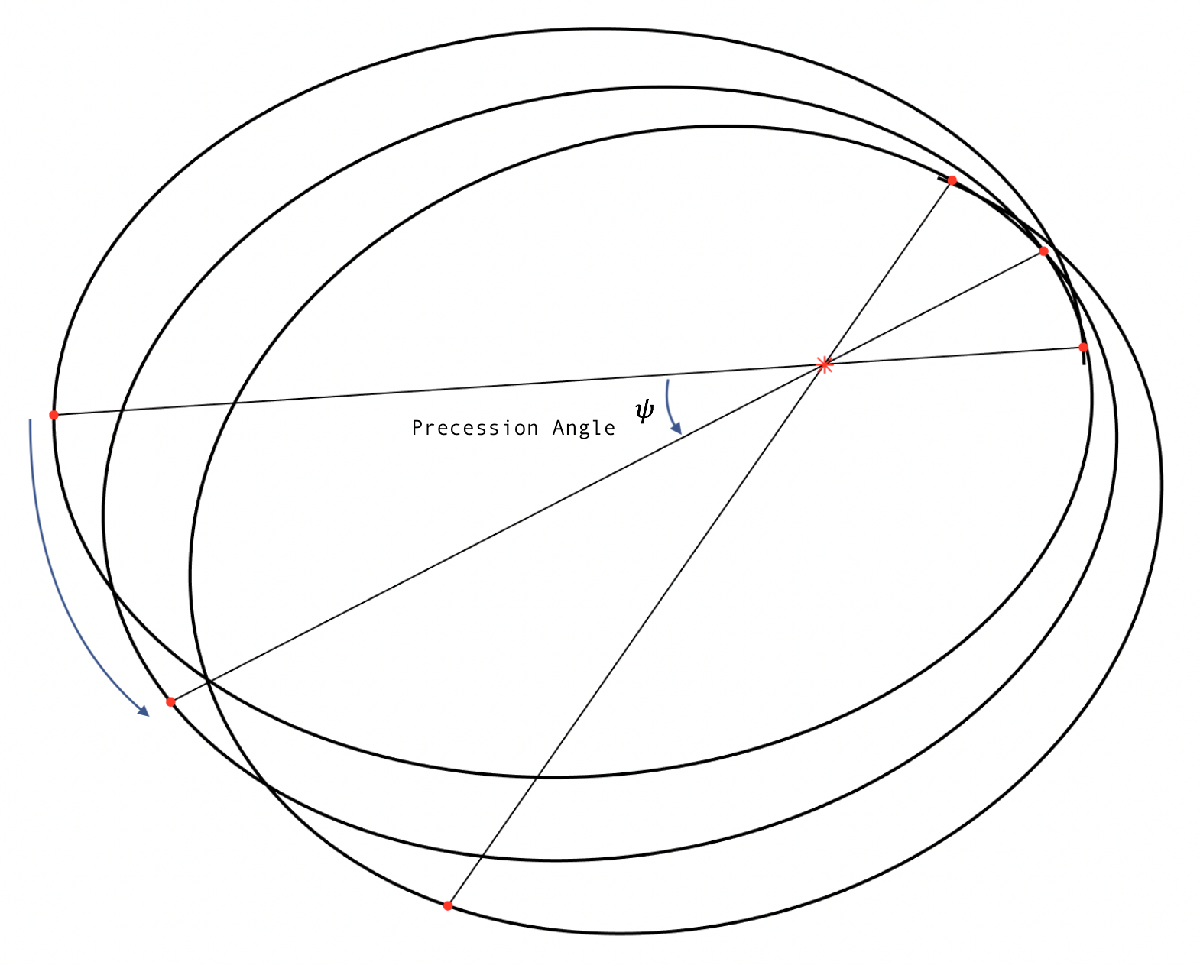

All of the planets in the solar system have a very slight precession due mainly to the gravitational force of the other planets and general relativity, but Mercury's orbit has the most pronounced precession and could be observed by astronomers in the 1800s.

#### History

The French astronomer Urbain Le Verrier was the first scientist to calculate the discrepancy in the precession of Mercury's orbit that would be explained by the theory of General Relativity over 50 years later. Le Verrier's main astronomical claim to fame was mathematically predicting the existance of Neptune due to its interference with the orbit of Uranus, so his hypothesis for the cause of the perihelion precession of Mercury was a planet closer to the sun that exerted gravitational force on Mercury and augmented its orbit. This hypothetical planet was never found, and other possible explanations for the precession such as multiple small bodies closely orbiting the sun and the oblateness of the sun were also ruled out. 

Le Verrier's 1859 calculations were slightly improved in 1895 by Simon Newcomb, a Canadian-American mathematician and astronomer.

-Newcomb calculations 1895

The extra precession of Mercury's orbit couldn't be explained until Einstein developed his General Theory of Relativity in the early 1900s. This was actually one of the three classical tests of General Relativity (the other two being the curvature of light rays by the gravitational field of the sun and the gravitational redshift of light emitted from distant stars) to comfirm the theory experimentally. General Relativity accurately predicts the extra 43 arcseconds of precession per century.

#### Computations and Numerical Analysis

If the effects from the other planets and general relativity are not taken into account, the equation for the radius of an ellipse can model the orbit of Mercury (1).


$$r=\frac{a\left(1-e^2 \right)}{1+e\;\cos \left(\theta \right)}$$


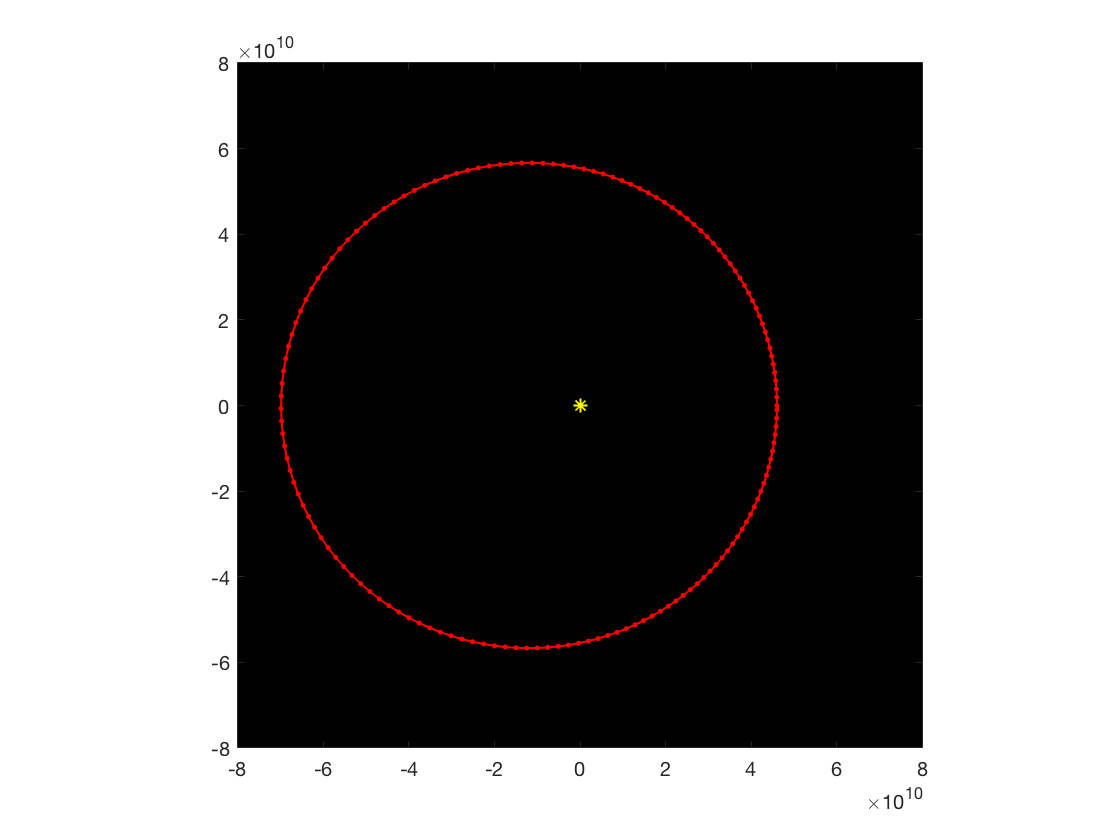

a = 57909050000; %semi-major axis of mercury (m)
e = 0.205630; %eccentricity of merciry's orbit

theta = linspace(0, (2*pi)*(365.25/87.969)*0.24,24*(2*pi)*(365.25/87.969)*0.24); %models one orbit
r = @(theta) a.*(1-e.^2)./(1+e.*cos(theta));
%converts polar coords to cartesian
x = @(r, theta) r.*cos(theta);
y = @(r, theta) r.*sin(theta);

plot(0,0,'y*')
hold on
set(gca, 'Color', 'k')
axis([-8e10,8e10,-8e10,8e10], 'square')
p1 = plot(x(r(theta), theta), y(r(theta), theta), 'Color', 'r', 'marker', '.', 'Linewidth', 1, "DisplayName", "None");

This method worked well for modeling the orbit of Mercury if only the gravitational force of the sun is taken into account. However, if the gravitational force of the other planets and the effects of general relativity are factored in, an easier approach is to calculate the precession of the orbit using the following formula and then shifting the position of Mercury (2)

-explain what this is more


$$\Delta \psi =\frac{1}{e}\int_0^{2\pi } g\left(r\right)\mathrm{cos}\left(\theta \right)d\theta$$


$g\left(r\right)$ is the ratio of the perturbing force to the gravitational force of the Sun.

To find $g\left(r\right)$ from another planet:


$$g\left(r\right)=\frac{M_P r^3 }{2M_S R_P \left({R_P }^2 -r^2 \right)}=\frac{M_P {\left(\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\right)}^3 }{2M_S R_P \left({R_P }^2 -{\left(\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\right)}^2 \right)}$$


Since all the variables in this expression are constants except for $\theta$, this can be integrated to solve for the precession of the orbit over one period.

a = 57909050000; %semi-major axis of mercury (m)
e = 0.205630; %eccentricity of merciry's orbit
msun = 1.9885e30;
mvenus = 4.867e24; %venus mass (kg)
Rvenus = 108208000000; %venus radius (m)
mearth = 5.976e24; %earth mass (kg)
Rearth = 149598023000; %earth radius (m)
mmars = 6.421e23; %mars mass (kg)
Rmars = 227939200000; %mars radius (m)
mjupiter = 1.899e27; %jupiter mass (kg)
Rjupiter = 778.57e9; %jupiter radius (m)
msaturn = 5.686e26; %saturn mass (kg)
Rsaturn = 1433.53e9; %saturn radius (m)
muranus = 8.681e25; %uranus mass (kg)
Ruranus = 2.87503e12; %uranus radius (m)
mneptune = 1.02413e26; %neptune mass (kg)
Rneptune = 4.504e12; %neptune radius (m)
G = 6.67408e-11;
c = 299792458; %speed of light (m/s)
RP = [Rvenus, Rearth, Rmars, Rjupiter, Rsaturn, Ruranus, Rneptune];
MP = [mvenus, mearth, mmars, mjupiter, msaturn, muranus, mneptune];

r = @(theta) a.*(1-e.^2)./(1+e.*cos(theta));

g = @(r, RP, MP) -MP.*r.^3./(2.*msun.*RP.*(RP.^2-r.^2));

deltapsiP = 0;
for i = 1:7
    int = @(theta) g(r(theta), RP(i), MP(i)).*cos(theta);
    deltapsiP = deltapsiP + (1/e)*integral(int, 0, 2*pi);
end
fprintf("Orbital precession due to planets: %f arcseconds per orbit; %f arcseconds per century", deltapsiP*(360*3600/(2*pi)), deltapsiP*(365.25*100/87.969)*360*3600/(2*pi))

Orbital precession due to planets: 1.281939 arcseconds per orbit; 532.264989 arcseconds per century

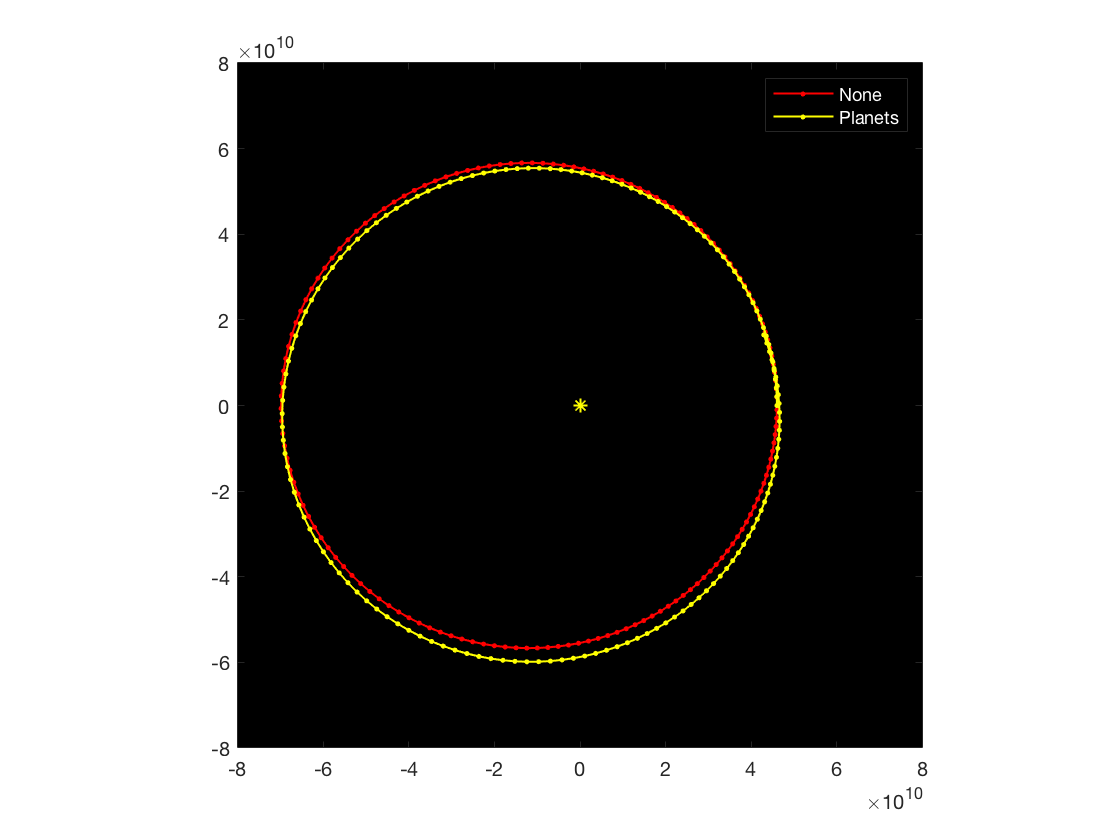

amp = 10000; %amplifies precession so it is visible in plot
x = @(r, theta, deltapsi) r.*cos(theta+amp*theta*deltapsi);
y = @(r, theta, deltapsi) r.*sin(theta+amp*theta*deltapsi);

p2 = plot(x(r(theta), theta, deltapsiP), y(r(theta), theta, deltapsiP), 'Color', 'y', 'marker', '.', 'Linewidth', 1, "DisplayName", "Planets");
legend([p1, p2],'TextColor', 'w')

The effect that general relativity has on the precession of Mercury's orbit can also be represented by $g\left(r\right)$ (2)


$$g\left(r\right)=\frac{3GM_S a\left(1-e^2 \right)}{c^2 r^2 }=\frac{3GM_S a\left(1-e^2 \right)}{c^2 {\left(\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\right)}^2 }$$


Again, since this equation is represented in terms of $\theta$, it can be integrated to find the precession of the orbit over one period.

r = @(theta) a.*(1-e.^2)./(1+e.*cos(theta));

g = @(r) 3*G*msun*a*(1-e^2)./(c^2.*r.^2);

int = @(theta) g(r(theta)).*cos(theta);
deltapsiGR = (1/e)*integral(int, 0, 2*pi);
fprintf("Orbital precession due to general relativity: %f arcseconds per orbit; %f arcseconds per century", deltapsiGR*(360*3600/(2*pi)), deltapsiGR*(365.25*100/87.969)*360*3600/(2*pi))

Orbital precession due to general relativity: 0.103519 arcseconds per orbit; 42.981256 arcseconds per century

The sum of these calculations agree with the observed precession of the perihelion of Mercury.

fprintf("Total orbital precession per century: %f arcseconds", (deltapsiP+deltapsiGR)*(365.25*100/87.969)*360*3600/(2*pi))

Total orbital precession per century: 575.246245 arcseconds

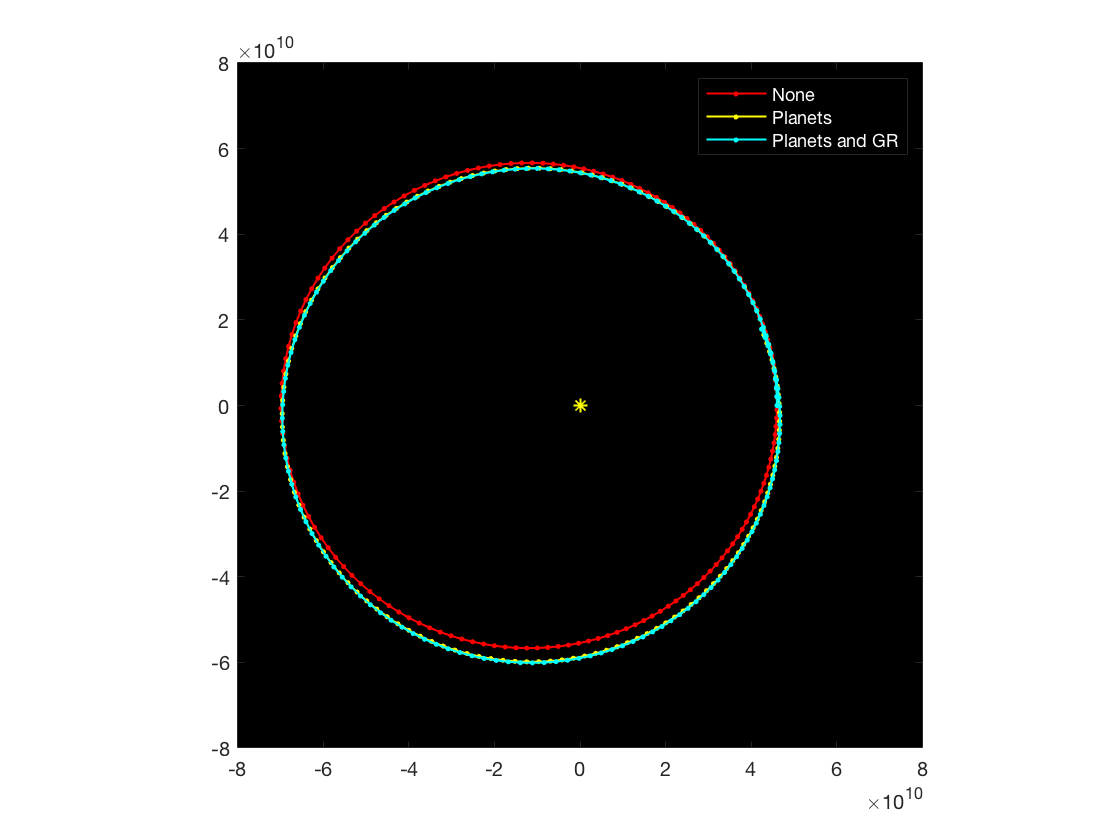

amp = 10000; %amplifies precession so it is visible in plot
x = @(r, theta, deltapsi) r.*cos(theta+amp*theta*deltapsi);
y = @(r, theta, deltapsi) r.*sin(theta+amp*theta*deltapsi);

p3 = plot(x(r(theta), theta, deltapsiP+deltapsiGR), y(r(theta), theta, deltapsiP+deltapsiGR), 'Color', 'c', 'marker', '.', 'Linewidth', 1, "DisplayName", "Planets and GR");
legend([p1, p2, p3],'TextColor', 'w')

#### Sources

1 V. A. Chobotov, *Orbital Mechanics *(American Institute of Aeronautics and Astronautics 2002)

2 B. Davies, *Elementary theory of perihelion precession *(Am. J. Phys. October 1983), p. 909

3 M. P. Price, W. F. Rush, *Nonrelativistic contribution to Mercury's perihelion precession *(Am. J. Phys. June 1979), p. 531

4 A. Einstein, *Relativity, the Special and General Theory *(Crown Publishers, New York 1961)

5 R. Hakim, *An Introduction to Relativistic Gravitation *(Cambridge University Press 1999)

6 W. Sheehan, R Baum, *Vulcan Chasers *(Astronomy December 1997, Vol. 25, Issue 12), p. 42

Masses and radii of planets and sun from Wikipedia